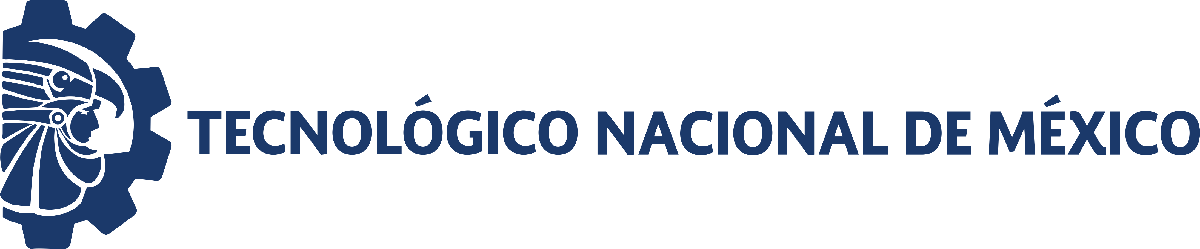                                 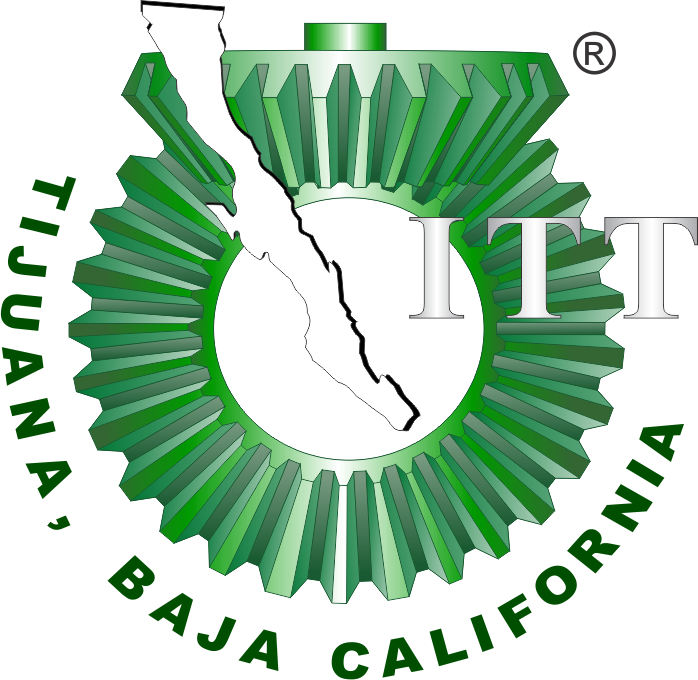

# Práctica Dos: Cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[Foto]

Nombre del alumno: José David Ramírez Ruiz

Número de control: 22212268

Correo institucional: l22212268**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

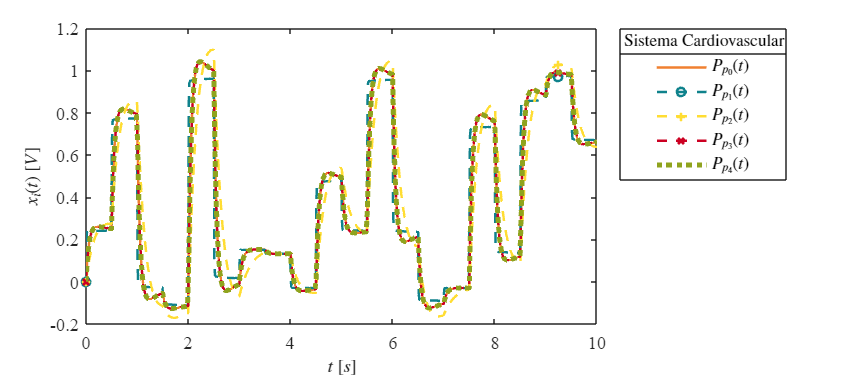

clc; clear; close all; warning('off','all')
tend = '10';
file = 'SistemaC';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
set_param('SistemaC/Ppa(t)','Minimum','-0.2');
set_param('SistemaC/Ppa(t)','Maximum','1');
set_param('SistemaC/Ppa(t)','Seed','106');
set_param('SistemaC/Ppa(t)','SampleTIme','0.5');
x = sim(file,parameters);
writematrix(x.Ppa,'signal.xlsx')
plotsignals(x.t,x.Pp0,x.Pp1,x.Pp2,x.Pp3,x.Pp4);

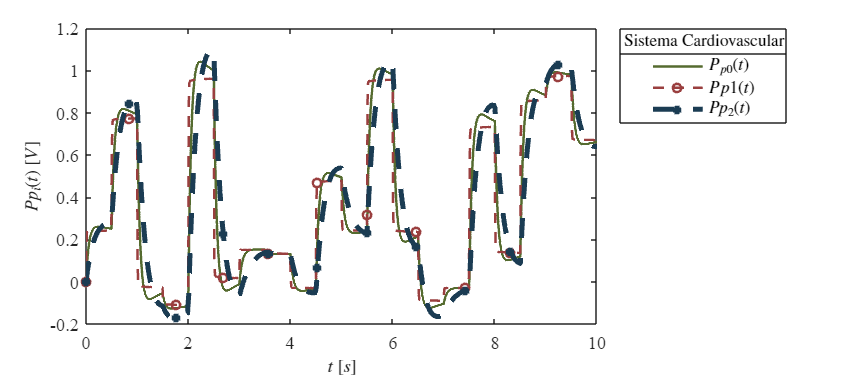

set_param('SistemaC/Ppa(t)','Minimum','-0.2');
set_param('SistemaC/Ppa(t)','Maximum','1');
set_param('SistemaC/Ppa(t)','Seed','106');
set_param('SistemaC/Ppa(t)','SampleTime','0.5');
x2 = sim(file,parameters);
plotsignals2(x2.t,x2.Pp0,x2.Pp1,x2.Pp2)

## Respuesta en lazo abierto

## Respuesta al impulso

## Respuesta a la rampa

## Respuesta a la función sinusoidal

## Función: Respuesta a las señales

function plotsignals(t,Pp0,Pp1,Pp2,Pp3,Pp4)
set(figure(),'Color','w')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;

mycolors = [240,128,48;
15,130,140;
255,221,51;
204,0,34;
143,163,30;
107,36,12;]/255;
colororder(mycolors)



p = plot(t,Pp0,'-',t,Pp1,'--o',t,Pp2,'--+',t,Pp3,'--x',t,Pp4,':',...
   'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:10000:length(t));
set(p(5), 'LineWidth',3)
L = legend('$P_{p_0}(t)$','$P_{p_1}(t)$','$P_{p_2}(t)$','$P_{p_3}(t)$','$P_{p_4}(t)$','$PID(t)$');
set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
title(L,['Sistema Cardiovascular'],'FontSize',10)

xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)



exportgraphics(gcf,['SistemaCardiovascular','.pdf'],'ContentType','vector')
exportgraphics(gcf,['SistemaCardiovascular','.png'],'ContentType','vector')
end

function plotsignals2(t,Pp0,Pp1,Pp2)
set(figure(),'Color','w')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;
mycolors = [85,107,47;
            154,63,63;
            27,60,83;
            152,161,188;
            51,56,160;
            249,122,0]/255;
colororder(mycolors)

p =  plot(t,Pp0,'-',t,Pp1,'--O',t,Pp2,'--+',...
     'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
set(p(3),'LineWidth',3);
 L = legend('$P_{p0}(t)$','$P{p1}(t)$','$P{p_2}(t)$');
 set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','on');

title(L,'Sistema Cardiovascular','FontSize',10)

 xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
 ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)


 exportgraphics(gcf,['SistemaCardiovascular_2','.pdf'],'ContentType','vector')
exportgraphics(gcf,['SistemaCardiovascular_2','.png'],'ContentType','vector')
end


